# Práctica 5. Interpolación por splines cúbicos.

## Implementar la interpolación mediante splines cúbicos de tipos I y II.

**a)** Para un vector $x=(x_0,\dots,x_n)$, que contiene los $n+1$ nodos de interpolación, otro vector $y=(y_0,\dots,y_n)$, que contiene sus respectivas imágenes, y un último vector $X=(X_1,\dots,X_N)$, deseamos obtener el valor de la interpolación por spline de tipo I en los puntos $X_i$. Lo implementaremos en el **APÉNDICE A**.

La función nos debe devolver, dados $x$, $y$, $X$:

- El vector $Y$ de $N$ coordenadas, imagen en los puntos $X$ del la interpolación por splines de tipo I generada con los $n+1$  puntos $(x_0,\dots,x_n)$.

**b)** Para un vector $x=(x_0,\dots,x_n)$, que contiene los $n+1$ nodos de interpolación, otro vector $y=(y_0,\dots,y_n)$, que contiene sus respectivas imágenes, y un último vector $X=(X_1,\dots,X_N)$, deseamos obtener el valor de la interpolación por spline de tipo II en los puntos $X_i$. Además, también necesitamos los valores de las derivadas en los extremos, $z_0$ y $z_n$. Lo implementaremos en el **APÉNDICE B**.

La función nos debe devolver, dados $x$, $y$, $X$, $z_0$, $z_n$:

- El vector $Y$ de $N$ coordenadas, imagen en los puntos $X$ del la interpolación por splines de tipo I generada con los $n+1$  puntos $(x_0,\dots,x_n)$.

**c)** Calcula los polinomios de interpolación anteriores de la función $f(x)=sin(x^2)$ en el intervalo $[-2,2]$ con los puntos equiespaciados dados. Representa gráficamente ambos y calcula el error en norma de cada aproximación.

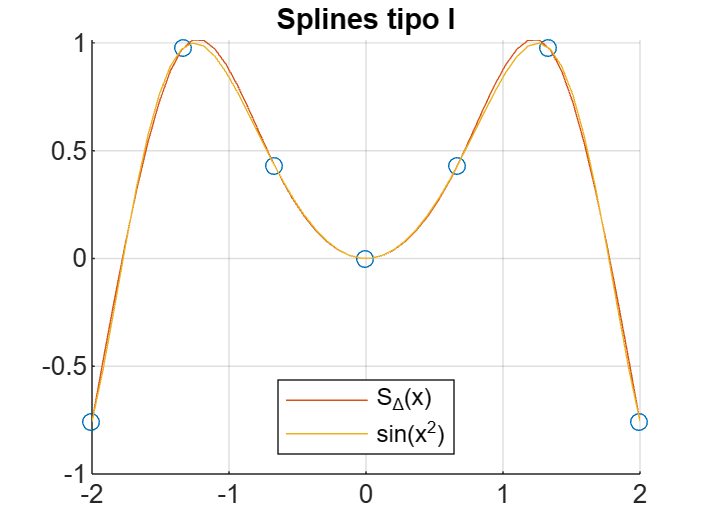

%Utiliza estos datos x, y
x=linspace(-2,2,7)';
y=sin(x.^2);
z0=2*x(1)*cos(x(1)^2);
zn=2*x(length(x))*cos(x(length(x))^2);

%Escribe a partir de aquí tu código
X = linspace(-2,2,50)';
Y1 = splinesTipoI(x,y,X);
Y2 = splinesTipoII(x,y,X,z0,zn);
Y3 = sin(X.^2);
% tiledlayout(2,1)
% nexttile
scatter(x,y)
title("Splines tipo I")
hold on
plot(X,Y1)
plot(X,Y3)
legend("","S_{\Delta}(x)","sin(x^2)", 'Location','south')
grid on
hold off

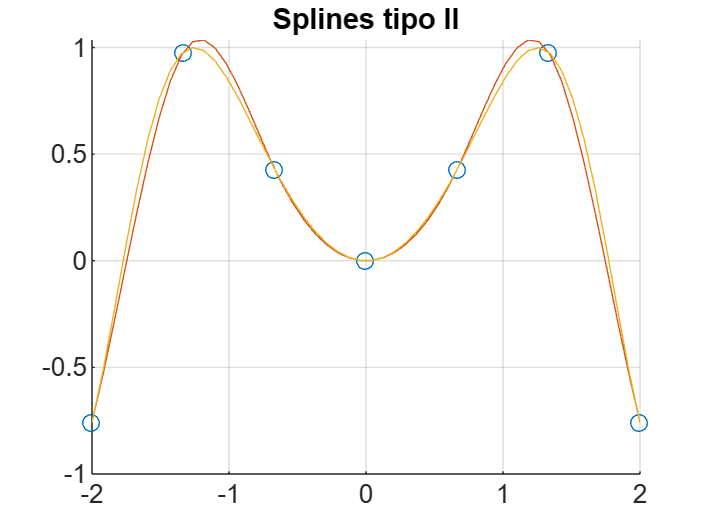

% nexttile
scatter(x,y)
title("Splines tipo II")
hold on
plot(X,Y2)
plot(X,Y3)
grid on
hold off


%Calculo error en norma de cada aproximacion
N = length(X);
disp("Error de cada aproximación");

Error de cada aproximación


e1 = sum(abs(Y1 - Y3)) / N

e1 = 0.0164

e2 = sum(abs(Y2 - Y3)) / N

e2 = 0.0360

### Apéndice A. Splines de tipo I

function Y = splines(x,y,X,tipo,z0,zn)


$$\begin{array}{l}
x=\left(x_1 ,\ldots,x_n \right)\\
y=\left(y_1 ,\ldots,y_n \right)
\end{array}$$


assert(tipo == 1 || tipo == 2);
n = length(x);
assert(n == length(y));
N = length(X);


$$\mu_j =\frac{x_j -x_{j-1} }{x_{j+1} -x_{j-1} },\;\;\;\;\;j=2,\ldots,n-1,\;\;\;\;\mu_n =0\;\;$$


mu = zeros(n, 1);
mu(2:n-1) = (x(2:n-1) - x(1:n-2)) ./ (x(3:n) - x(1:n-2));
if(tipo == 2)
    mu(n) = 1;
end


$$\lambda_j =\frac{x_{j+1} -x_j }{x_{j+1} -x_{j-1} }\;\;\;\;\;j=2,\ldots,n-1\;\;\;\;\;\;\lambda_1 =0$$


lambda = zeros(n, 1);
lambda(2:n-1) = (x(3:n) - x(2:n-1)) ./ (x(3:n) - x(1:n-2));
if(tipo == 2)
    lambda(1) = 1;
end


$$b_j =\frac{6}{x_{j+1} -x_{j-1} }\left(\frac{y_{j+1} -y_j }{x_{j+1} -x_j }-\frac{y_j -y_{j-1} }{x_j -x_{j-1} }\right)\;\;\;\;\;\;\;j=2,\ldots,n-1\;\;\;\;\;\;\;b_1 =b_n =0$$


b = zeros(n,1);
b(2:n-1) = 6 * ((y(3:n)-y(2:n-1))./(x(3:n)-x(2:n-1)) - (y(2:n-1)-y(1:n-2))./(x(2:n-1)-x(1:n-2))) ./ (x(3:n) - x(1:n-2));
if(tipo == 2)
    b(1) = 6/(x(2)-x(1))*((y(2)-y(1))/(x(2)-x(1)) - z0);
    b(n) = 6/(x(n)-x(n-1))*(zn - (y(n)-y(n-1))/(x(n)-x(n-1)));
end

Ahora, resolvemos el sistema tridiagonal AM = d

A = diag(mu(2:n),-1) + 2*diag(ones(n,1)) + diag(lambda(1:n-1),1);
M = A\b;
S = zeros(n-1,4); % S(i,j) es el coeficiente de grado 3-j+1 del polinomio en el intervalo [xi,x(i+1)]
S(:,4) = y(1:n-1);

Calculamos los coeficientes teniendo en cuenta que:


$$S|_{\left\lbrack x_j ,x_{j+1} \right\rbrack } \left(x\right)={a\left(x-x_j \right)}^3 +{b\left(x-x_j \right)}^2 +c\left(x-x_j \right)+d$$



$$\begin{array}{l}
{a\left(x-x_j \right)}^3 =ax^3 -a3x_j x^2 +a3x_j^2 x-ax_j^3 \\
{b\left(x-x_j \right)}^2 ={\textrm{bx}}^2 -2{\textrm{bx}}_j x+{\textrm{bx}}_j^2 \\
c\left(x-x_j \right)=\textrm{cx}-{\textrm{cx}}_j 
\end{array}$$


Por lo tanto:


$$S|_{\left\lbrack x_j ,x_{j+1} \right\rbrack } \left(x\right)=a\;x^3 +\left(-{\textrm{a3x}}_j +b\right)x^2 +\left(3{\textrm{ax}}_j^2 -2{\textrm{bx}}_j +c\right)x+\left(-{\textrm{ax}}_j^3 +{\textrm{bx}}_j^2 -{\textrm{cx}}_j +d\right)$$


a = (M(2:n)-M(1:n-1)) ./ (6*(x(2:n)-x(1:n-1)));
b2 = M(1:n-1) / 2;
c = (y(2:n)-y(1:n-1)) ./ (x(2:n)-x(1:n-1)) - (M(2:n) + 2*M(1:n-1))/6 .* (x(2:n)-x(1:n-1));
d = y(1:n-1);

S(:,1) = a;
S(:,2) = -3*a.*x(1:n-1) + b2;
S(:,3) = 3*a.*x(1:n-1).^2 - 2*b2.*x(1:n-1) + c;
S(:,4) = -a.*x(1:n-1).^3 + b2.*x(1:n-1).^2 -c.*x(1:n-1) + d;

Y = zeros(N,1);
for i = 1:N
    assert(X(i) >= x(1) && X(i) <= x(n));
    for j = 2:n
        if(X(i) <= x(j))
            Y(i) = polyval(S(j-1,:),X(i));
            break;
        end
    end
end
end

function Y = splinesTipoI(x,y,X)
    Y = splines(x,y,X,1,0,0);
end

### Apéndice B. Splines de tipo II

function Y = splinesTipoII(x,y,X,z0,zn)
    Y = splines(x,y,X,2,z0,zn);
end